## 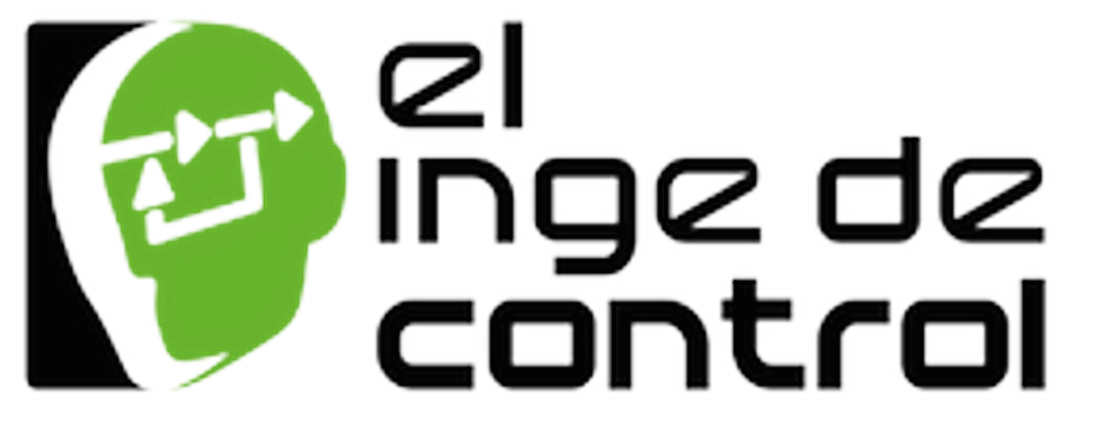

# **Taller: Control Robusto y Estocástico**

## Tema: Incertidumbre No Estructurada

## Dr. Julio A. García Rodríguez

**EXERCISE**

G0 = nominal model used to design the controller 

G1 to G6  = possible physical plants or experiments 

W = Weighting function covering discrepancies 

Delta  = unknown dynamics

% Part A: Nominal model

clear, clc, close all;

s = tf('s');          

G0 = 1/(0.2*s + 1); %Nominal Servomotor Model
G0


pole(G0)
pzmap(G0)
grid on

**POSSIBLE UNCERTAIN BEHAVIOR ** 

In a real-world application, G1, G2, ..., G6 could be: 

- six experiments on the same motor,

- six manufactured motors,  

- the motor under different loads,

- measurements at different temperatures,

- different operating points.

% Part B: Creation of uncertain plants
dyn1 = 80/(s + 80);
G1  = G0*dyn1;
G1



wn2   = 60;       
zeta2 = 0.18;   
dyn2 = wn2^2/(s^2 + 2*zeta2*wn2*s + wn2^2);
G2  = G0*dyn2;
G2


Tdelay3 = 0.006;                       
[numD3,denD3] = pade(Tdelay3,2);
dyn3 = tf(numD3,denD3);
G3 = G0*dyn3;
G3


dyn4 = 100/(s + 100);
wn4   = 90;
zeta4 = 0.25;
dyn41 = wn4^2/(s^2 + 2*zeta4*wn4*s + wn4^2);
G4 = G0*dyn4*dyn41;
G4


Tdelay5 = 0.004;
[numD5,denD5] = pade(Tdelay5,2);
dyn5 = tf(numD5,denD5);
dyn51 = 70/(s + 70);
G5 = 1.03*G0*dyn5*dyn51;
G5

wn6   = 110;
zeta6 = 0.15;
dyn6 = wn6^2/(s^2 + 2*zeta6*wn6*s + wn6^2);
G6 = 0.97*G0*dyn6;
G6

Garray = stack(1,G1,G2,G3,G4,G5,G6);
Garray


Although we use different equations to create these plants, it is assumed that the designer does not know them. The designer only has the results of six tests.

% Part C: Step response

t = 0:0.01:5;

figure
step(G0,Garray,t)
grid on

title('Nominal model and possible plants');
ylabel('Velocity');

*From Class Slides:* 

For multiplicative uncertainty we take the relative error

% Part D: Frequency response

w = logspace(-1,3,300);
Gdata = frd(Garray,w);

Err_i = (Gdata - G0)/G0;

figure
bodemag(Err_i,{0.1,1000})
grid on

title('Relative Multiplicative Errors');
xlabel('Frequency');
ylabel('Magnitude');

In low frequencies, the magnitude of the relative error is less than -20dB. We can state that

#### 
$$G_i(jw) \approx G_0(jw)$$


because

### 
$$\left| E_i(jw) \right| \approx 0.$$


But when ω approaches 60, 80, 90, or 110 rad/s, the neglected dynamics no longer appear equal to one. So

####  
$$G_i(jw) \not \approx G_0(jw)$$


and the relative error increases. 

We now search for a function W(s) whose magnitude covers all errors.

#### 
$$\left| E_i(jw) \right| \leq \left| W(jw) \right|$$


for all the plants and frequencies in the problems.

% Part E: Fit the W.  

orderW = 3;
[Gunc,Info] = ucover(Gdata,G0,orderW,'InputMult');
W = Info.W1;
tf(W)
zpk(W)

The obtain system has the form

#### 
$$G_{unc} (s) = G_0(s) [1 +W(s)\Delta(s)]$$


figure
bodemag(Err_i,'--',W,{0.1,1000});
grid on

title('Relative errors and Weightingh function W');
legend('Errors','Third order W Function','Location','southeast')

Gunc.NominalValue
Gunc.Uncertainty

Try higher order

orderW = 5;
[Gunc,Info] = ucover(Gdata,G0,orderW,'InputMult');
W = Info.W1;

figure
bodemag(Err_i,'--',W,{0.1,1000});
grid on

title('Relative errors and Weightingh function W');
legend('Errors','High order W Function','Location','southeast')

The object created by MATLAB not only contains the six original plants but also includes all plants of the form:

This is what the unstructured uncertainty approach addresses. We view the original plant as a large family of plants with many added unknown dynamics, all of which are bounded by W(s).

Therefore, for robust control, the problem is formulated as follows: "***designing a controller that works not only for the nominal model but also for all unknown dynamics consistent with the observed discrepancies***."